# Question 5

Read input file:

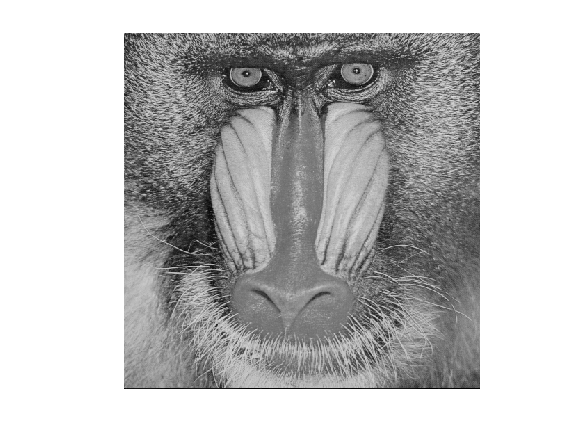

im = imread("/MATLAB Drive/images/mandrill.tif");
imshow(im)

First we record the size of the original image:

im_sz = size(im);

im_sz =    512   512


Then we shrink to an 4x8 image such that there are only 32 possible pixels. I also chose to use the bilinear to maintain a little bit more influence from all of the pixels that are lost.

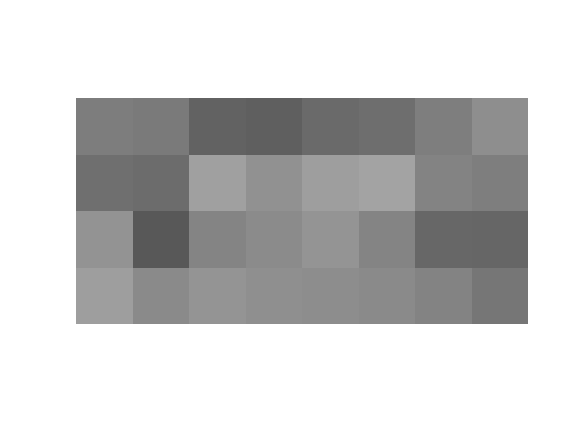

im_small = imresize(im, [4,8],"bilinear");
imshow(im_small)

Finally, scale the 4x8 image back up to the original size of 512x512, using the nearest neighbor method to insure there are no new pixel values interpolated

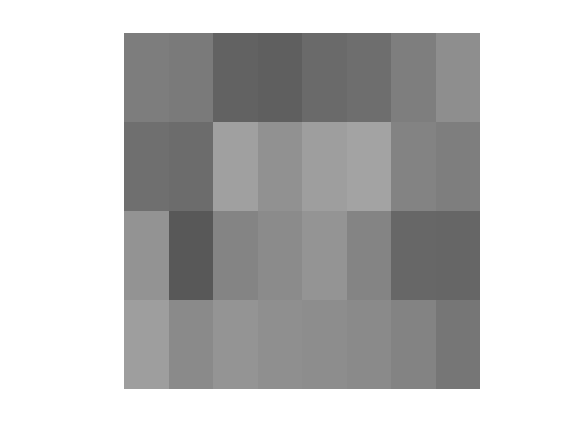

im_scaled = imresize(im_small, im_sz,"nearest");
imshow(im_scaled)

We can check to see if this image is effectivly in 32 level grayscale by checking if it have less than 33 unique values

unique(im_scaled(:))

ans = 26x1 uint8 column vector
    88
    95
    98
   102
   103
   106
   108
   110
   111
   118


Since the unique number of pixel values =< 32, the original image has effectively been converted into a 32  grayscale level interpolation.

Although the image is very hard to make out, if you squint you can see the outline of the mandrill's head. Although this did give the required 32-leveled output, the quality of the resulting image is inferior to the normal quantizing operation.